# Lo standard JPEG

In questa dispensa interattiva studieremo il funzionamento dello standard di compressione d'immagini JPEG. Vedremo il funzionamento di un codificatore e decodificatore JPEG in tutte le sue parti con due eccezioni:

- Non è mostrata l'implementazione del decodificatore lossless (cosiddetto "pseudo-Huffman"), che è semplice concettualmente ma non altrettanto per l'implementazione

- Non creeremo tutte le strutture della sintassi JPEG, in particolare gli headers ed i markers: essi sono importanti nella pratica, ma la loro implementazione è banale e non interessante

Il codice Matlab è spiegato, ma l'importante è capire la metodologia più che l'implementazione. 

### Si parte!

Cominciamo con il caricare e mostrare un'immagine a colori. 

clear variables
rgb_in = imread('colors_small.bmp');

Effettuiamo la trasformazione di spazio di colore, ottenendo l'immagine YCbCr: 

ycbcr = rgb2ycbcr(rgb_in);
y = ycbcr(:,:,1);
cb = ycbcr(:,:,2);
cr = ycbcr(:,:,3);

Mostriamo l'immagine a colori e la sua versione a livelli di grigio:

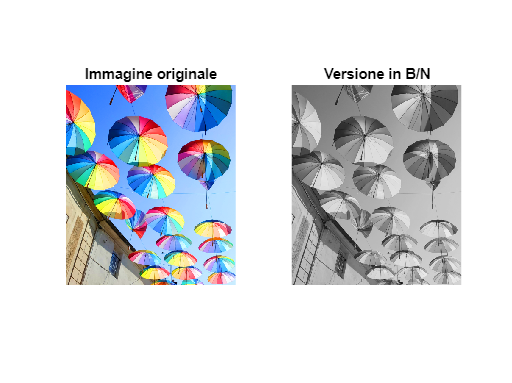

figure; 
subplot(121); image(rgb_in); axis image; axis off; title('Immagine originale')%impixelinfo
subplot(122); image(y); colormap("gray"); axis image; axis off; title('Versione in B/N')%impixelinfo 

Lavoreremo solo sulla componente di luminanza Y.

## Preprocessing

Il primo passo di JPEG consiste nel "centrare" l'immagine: si rimuove il centro dell'intervallo di valori. In questo modo, il segnale varia tra -128 e 127. 

y0 = double(y)-128; 

## Trasformata DCT

Poi si calcola la trasformata DCT sui blocchi 8x8. Per eseguire tale operazione usiamo la funzione Matlab `blockproc`. Essa ammette in ingresso l'immagine, la dimensione del singolo blocco, e un puntatore a funzione che in Matlab è chiamato `handler`. A sua volta, l'handler viene definito usando l'operatore `@` . L'handler da usare in  `blockproc` deve accettare in ingresso una struct con un campo chiamata `data` (il blocco di pixel) sul quale fare l'operazione considerata.

blockBasedDCT = @(block_struct) dct2(block_struct.data);
blk_dct = blockproc(double(y0),[8 8], blockBasedDCT);

Mostriamo adesso un blocco di pixel dell'immagine e la sua DCT. Per facilità di visualizzazione, mostriamo il blocco a colori, ma la DCT viene calcolata solo sulla componente di luminanza Y. 

La posizione del blocco è scelta con gli slider. Cliccare su "Run section" per eseguire questa parte di codice. 

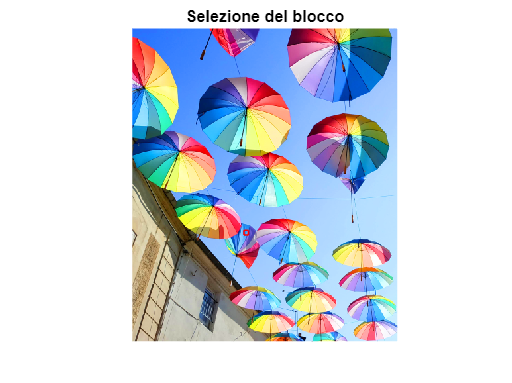

rowPos = 305;
colPos = 169;
 

figure; image(rgb_in); axis image; axis off; 
drbx = @(x1,x2,y1,y2) line([x1 x1 x1 x2; x2 x2 x1 x2],[y1 y2 y1 y1; y1 y2 y2 y2]);
hold on; h=drbx(colPos,colPos+7,rowPos,rowPos+7); hold off;
set(h,'linewidth',1,'color', 'red'); title('Selezione del blocco');

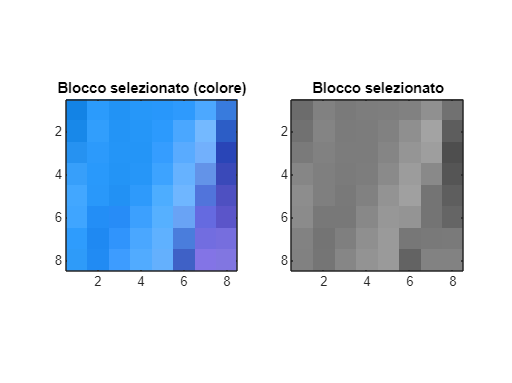

colorBlock = rgb_in(rowPos:rowPos+7,colPos:colPos+7,:); 
grayBlock = double(y(rowPos:rowPos+7,colPos:colPos+7,:));
dctBlock = blk_dct(rowPos:rowPos+7,colPos:colPos+7); 
figure; subplot(121); image(colorBlock);  axis image; title('Blocco selezionato (colore)')
subplot(122); image(grayBlock); colormap(gray); axis image; title('Blocco selezionato')

fprintf('DCT del blocco selezionato:\n'); disp(dctBlock)

DCT del blocco selezionato:
    8.5000    8.3118  -58.6668   59.0889  -20.2500   19.5289  -21.4305   13.2158
  -11.1124  -14.9869    7.5636   17.2810  -61.6096   12.7894  -15.6697   -9.6675
   -3.6491  -18.4206   13.0925  -52.2489   19.6353    1.9674  -20.7619   15.2069
   -2.6440    1.5572   -0.5667    4.4888   12.9520  -16.1413   15.6374  -13.4473
   -0.5000    3.6268    5.0842   -7.8515    8.7500   -6.9879    5.7414   -1.1157
   -4.1934   -1.1510    0.5139   -5.1079    4.7632   -0.6197    1.4921    0.7236
   -2.2769    2.5903   -1.5119    2.0108   -0.2858    2.0493   -0.3425    0.3944
   -0.6629    0.8658   -0.8129   -1.9558    1.7495   -2.6206    0.7082    0.1178



## **Quantizzazione**

Dopo la trasformata c'è la quantizzazione uniforme, effettuata tramite l'operatore $\textrm{round}$

Ricordiamo che la quantizzazione uniforme consiste nel trasformare il numero reale $x$ in un intero, detto indice di quantizzazione: $x_{\textrm{ind}} =Q\left(x,\Delta \;\right)=\textrm{round}\left(\frac{x}{\Delta }\right)$. Tale indice viene poi utilizzato in decodifica per ricostruire il valore di $x$. Il valore ricostruito è $\tilde{x} =\Delta \;x_{\textrm{ind}} =\Delta \;\textrm{round}\left(\frac{x}{\Delta \;}\right)$, cioè il multiplo intero di $\Delta \;$più vicino a $x$. Ne risulta quindi che l'errore massimo di quantizzazione è $\frac{\Delta }{2}$. Quindi valori grandi di $\Delta \;$ implicano una "*forte*" quantizzazione ed un tasso di codifica (numero di bit necessari per codificare il valore quantizzato) piccolo, mentre valori piccoli di $\Delta \;$implicano una migliore qualità di ricostruzione ma un tasso richiesto più grande. 

JPEG permette di definire un diverso valore del passo di quantizzazione $\Delta \;$per ogni frequenza spaziale. In altre parole, si definisce una *tabella di quantizzazione* 


$$q:\;\left(i,j\right)\in {\left\lbrace 1,2,\ldots,8\right\rbrace }^2 \to \left\lbrace 1,2,\ldots256\right\rbrace$$


Cioè per ogni coefficiente DCT in posizione $\left(i,j\right)$ nel blocco trasformato, si definisce un passo di quantizzazione tra 1 e 256. Tale tabella è usata per quantizzare tutti i blocchi dell'immagine. 

Se allora $\textrm{DCT}\left(i,j\right)$ è il generico coefficiente DCT di un blocco dell'immagine, dopo la quantizzazione otteniamo degli indici: 


$${\textrm{DCT}}_{\textrm{ind}} =\textrm{round}\left(\frac{\textrm{DCT}\left(i,j\right)}{q\left(i,j\right)}\right)$$


È importante notare che lo standard **non definisce la tabella di quantizzazione**, che invece viene scelta dal codificatore ed inserita nel file JPEG (infatti essa è necessaria al decodificatore per ricostruire i valori quantizzati a partire dagli indici interi). Perché la norma non definisce la tabella? Perché così ogni implementazione del codificatore può scegliere la strategia di quantizzazione più adeguata. 

Per esempio, la teoria della codifica con trasformata fornisce un valore ottimale del tasso di codifica di ogni coefficiente in funzione dell'insieme delle varianze dei coefficienti stessi. Da tali valori di tasso e possibile, sotto opportune ipotesi, determinare i valori ottimali della tabella. 

Tuttavia c'è un altro approccio che è molto più comune e che è diventato una standard *de facto* (cioè è di prassi sempre impiegato, anche se non è obbligatorio). Sono stati condotti degli studi sulla qualità percepita ed è stato rilevato che, a parità di tasso di codifica, la seguente tabella di quantizzazione comporta le immagini visualmente migliori: 

q_mtx1 =     [16 11 10 16 24 40 51 61; 
            12 12 14 19 26 58 60 55;
            14 13 16 24 40 57 69 56; 
            14 17 22 29 51 87 80 62;
            18 22 37 56 68 109 103 77;
            24 35 55 64 81 104 113 92;
            49 64 78 87 103 121 120 101;
            72 92 95 98 112 100 103 99];

Notare che vengono scelti valori piccoli in alto a sinistra e grandi in basso a destra. Perché? Ci sono due ordini di motivi. Innanzitutto, la DCT è una trasformata che "sparsifica" il segnale concentrandone l'informazione nelle componenti a bassa frequenza (quindi in alto a sinistra). Quindi tale tabella non è dissimile da quella che si otterrebbe utilizzando l'approccio teorico fornito dalla teoria della quantizzazione citata sopra. Inoltre, e veniamo qui al second ordine di motivi, tale tabella rispecchia la sensibilità dell'osservatore umano medio alle diverse frequenze spaziali rappresentate dai coefficienti DCT. Siccome noi siamo più sensibili alle frequenze basse e medio basse, i valori più piccoli del passo di quantizzazione (che permettono una rappresentazione più precisa) corrispondono proprio a queste aree. 

Tuttavia è poco pratico avere una sola tabella di quantizzazione. Cosa fare se si vuole comprimere di più l'immagine? o se si vuole una qualità ancora migliore? 

La soluzione più semplice e di gran lunga più comune è quella di usare un fattore di scala $\textrm{SF}$. La tabella `q_mtx_1` è scalata moltiplicandola per $\frac{\textrm{SF}}{100}$

In questo modo, se $\textrm{SF}=100$ la matrice non cambia; se $\textrm{SF}<100$ la matrice viene scalata verso valori più piccoli e quindi la qualità dell'immagine migliora. Se invece $\textrm{SF}>100$ la matrice viene scalata verso valori più grandi e quindi la qualità peggiora. 

Siccome è poco intuitivo scegliere un valore si $\textrm{SF}$, viene definito un cosidetto parametro di qualità $Q$, che varia da 1 a 100. (La scelta del simbolo non è felice, visto la possibile confusione con la quantizzazione). La relazione tra $Q$ e $\textrm{SF}$ è la seguente:  

Quindi, quando la qualità è 1 (in alcuni software di trattamento immagini si indica "1%") il fattore di scala è 5000, cioè la tabella di quantizzazione è scalata di un valore 50. Se invece la qualità è massima ("100%") la tabella è scalata di un fattore $\frac{1}{100}$  . Siccome i valori della tabella devono essere comunque interi positivi, si usa l'approssimazione al prossimo valore intero. Si tagliano anche i valori più grandi di 256, in modo da poter rappresentare ogni valore della tabella su di un singolo byte.

Q = 30;
SF = (Q==100)+(Q<=99&&Q>50)*(200-2*Q)+ (Q<=50)*(5000/Q);
q_mtx = ceil(q_mtx1*SF/100);
q_mtx(q_mtx>256)=256; % Dove il valore supera 256, si riporta a 256
fprintf('Tabella di quantizzazione q:\n'); disp(q_mtx1)

Tabella di quantizzazione q:
    16    11    10    16    24    40    51    61
    12    12    14    19    26    58    60    55
    14    13    16    24    40    57    69    56
    14    17    22    29    51    87    80    62
    18    22    37    56    68   109   103    77
    24    35    55    64    81   104   113    92
    49    64    78    87   103   121   120   101
    72    92    95    98   112   100   103    99



fprintf('Tabella di quantizzazione riscalata:\n'); disp(q_mtx)

Tabella di quantizzazione riscalata:
    27    19    17    27    40    67    85   102
    20    20    24    32    44    97   100    92
    24    22    27    40    67    95   115    94
    24    29    37    49    85   145   134   104
    30    37    62    94   114   182   172   129
    40    59    92   107   135   174   189   154
    82   107   130   145   172   202   200   169
   120   154   159   164   187   167   172   165



Effettuiamo ora la quantizzazione di tutti i blocchi DCT, usando l'opportuno handler di funzione e usando `blocproc`

qfun = @(block_struct) round(block_struct.data./q_mtx);
quant_dct = blockproc(blk_dct,[8 8], qfun);


Mostriamo ora di nuovo il blocco di coeff. DCT, il blocco di indici di quantizzazione, e mostriamo anche i coefficienti ricostruti: 

fprintf('Blocco di coeff. DCT:\n');disp(dctBlock);

Blocco di coeff. DCT:
    8.5000    8.3118  -58.6668   59.0889  -20.2500   19.5289  -21.4305   13.2158
  -11.1124  -14.9869    7.5636   17.2810  -61.6096   12.7894  -15.6697   -9.6675
   -3.6491  -18.4206   13.0925  -52.2489   19.6353    1.9674  -20.7619   15.2069
   -2.6440    1.5572   -0.5667    4.4888   12.9520  -16.1413   15.6374  -13.4473
   -0.5000    3.6268    5.0842   -7.8515    8.7500   -6.9879    5.7414   -1.1157
   -4.1934   -1.1510    0.5139   -5.1079    4.7632   -0.6197    1.4921    0.7236
   -2.2769    2.5903   -1.5119    2.0108   -0.2858    2.0493   -0.3425    0.3944
   -0.6629    0.8658   -0.8129   -1.9558    1.7495   -2.6206    0.7082    0.1178



blk_quant_indexes= quant_dct(rowPos:rowPos+7,colPos:colPos+7); 
fprintf('Valori quantizzati:\n');disp(blk_quant_indexes.*q_mtx);

Valori quantizzati:
     0     0   -51    54   -40     0     0     0
   -20   -20     0    32   -44     0     0     0
     0   -22     0   -40     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0



fprintf('Indici di quantizzazione:\n');disp(blk_quant_indexes); 

Indici di quantizzazione:
     0     0    -3     2    -1     0     0     0
    -1    -1     0     1    -1     0     0     0
     0    -1     0    -1     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0



**Cambiate i valori del fattore di qualità ed osservate l'effetto su tali matrici. **

## **Codifica lossless**

Il primo passo della codifica lossless consiste nella scansione a zig-zag del blocco degli indici di quantizzazione. Ecco il risultato: 

fprintf('Scansione a zigzag:\n'); disp(zigzagscan(blk_quant_indexes))

Scansione a zigzag:
     0     0    -1     0    -1    -3     2     0    -1     0     0     0     0     1    -1     0    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



Effettuiamo ora la codifica entropica dei coefficienti della DCT, cominciando dal coefficiente "DC", cioè quello in alto a sinistra. 

Ricordiamo che si utilizza una codifica predittiva (differenziale) usando come predittore il coefficiente DC del blocco precedente. Utilizziamo una funzione Matlab che gestisce anche i casi particolari (primo blocco, blocchi sulla prima colonna).

previousBlockQuantizedDC = prevDC(quant_dct, rowPos,colPos); 

Utilizziamo poi la funzione `block_entropy_coding` che effettua la codifica lossless del blocco corrente

bits=block_entropy_coding(blk_quant_indexes,previousBlockQuantizedDC)

Codifica DC
Valore DC:0	Predittore:1
DC_P	Cat	Bits
 -1      1	0100
------------

Codifica AC
#AC    Run    Cat    Value   Bits
  1      1      1     -1     1100 0
  2      1      1     -1     1100 0
  3      0      2     -3     01 00
  4      0      2      2     01 10
  5      1      1     -1     1100 0
  6      4      1      1     111011 1
  7      0      1     -1     00 0
  8      1      1     -1     1100 0
  9      0      1     -1     00 0
EOB                          1010
------------


bits = '0100110001100001000110110001110111000110000001010'

Dopo aver calcolato l'errore di predizione `DC_P`, se ne trova la categoria $k\;$tramite la formula $k=\lceil \;\log_2 \;|{\textrm{DC}}_{\mathrm{P}} |+1\rceil \;$

In altre parole, la categoria 0 contiene il valore 0, la categoria 1 contiene $\pm 1$, la categoria 2 contiene $\pm 2$ e $\pm 3$, la categoria 3 contiene $\pm 4,\pm 5,\pm 6,\pm 7$ e la generica categoria $k>0$ contiene $2^k$ valori: $\left.\pm 2^{k-1} ,\;\pm {\left(2\right.}^{k-1} +1\right),\ldots,\pm \left(2^k -1\right)$

La categoria è codificata con un opportuno codice a prefisso che rappresenta ognuna delle possibili 12 categorie (da 0 a 11). Poi, il valore è codificato con $k$ bit. Se il valore è positivo, esso è direttamente rappresentato su $k$bits. Se è negativo, se ne calcola il modulo, lo si rappresenta su $k$ bit e poi se ne calcola il complemento a 2 bit per bit. 

Per i coefficienti AC si calcola ugualmente la categoria, ma si considera anche il numero di coefficienti nulli che precedono il coefficiente da codificare. Tale numero è detto "run" ($R$). La coppia $R,k$è codificata con un'opportuno codice a prefisso, mentre il valore del coefficiente è codificato come nel caso DC.

Si noti come la codifica per categoria valore permetta di codificare valori piccoli con codeword più corte. Inoltre si noti che la categoria serve a stabilire quanti bit saranno usati per codificare il valore. In questo modo si crea automaticamente un codice istantaneo: la categoria (o la coppia R/C) sono codificate su un codice istantaneo, ed una volta nota la categoria si sa esattamente quanti bit bisogna leggere per il valore. Se il primo bit del valore è `1` allora il segno è positivo. Se il primo bit è `0` allora si fa il complemento a 2, si passa da binario a decimale e poi si usa il segno meno. 

Infine, il numero di bit per pixel del blocco si ottiene semplicemente: 

bpp = numel(bits)/64

bpp = 0.7656

Per effettuare la codifica di tutta l'immagine bisogna ripetere la codifica lossless su ogni blocco 8x8, in ordine *raster-scan*. Il codice seguente non è inserito nello script perché rallenterebbe troppo l'esecuzione (ma comunque siamo nell'ordine della decina di secondi). 

## Immagine decodificata

Possiamo ricostruire l'immagine decodificata anche senza effettuare la codifica / decodifica lossless, perché tali operazioni per definizione non alterano il contenuto dei dati. 

Si tratta allora di passare dagli indici di quantizzazione ai valori quantizzati (talvolta tale operazione è detta "quantizzazione inversa", con abuso di terminologia perché la quantizzazione non è invertibile), e poi di effettuare la DCT inversa. Effettuiamo tali operazioni sempre con l'uso di `blocproc`.

Alla fine, bisognerà aggiungere di nuovo 128 all'immagine. 

iqfun = @(block_struct)  q_mtx.*(block_struct.data); % "Quantizzazione inversa" 
iqData =  blockproc(quant_dct,[8 8], iqfun); % Applichiamo la QI agli indici di quant. 
idctfun = @(block_struct) idct2( double(block_struct.data) ); % DCT inversa
reconstruct = uint8(blockproc(iqData,[8 8], idctfun)+128); % Applichiamo idct e aggiungiamo 128

Ecco i risultati: 

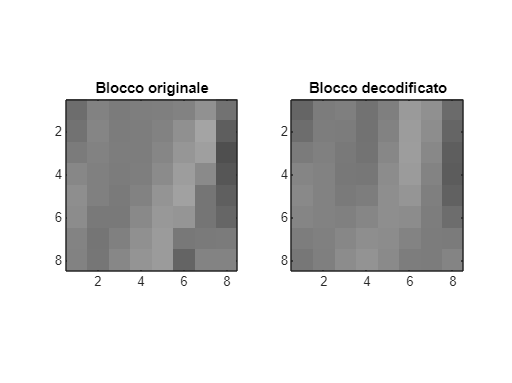

figure;
subplot(121); image(y(rowPos:rowPos+7,colPos:colPos+7)); axis image; title('Blocco originale'); colormap(gray(256))
subplot(122); image(reconstruct(rowPos:rowPos+7,colPos:colPos+7)); axis image; title('Blocco decodificato'); colormap(gray(256))

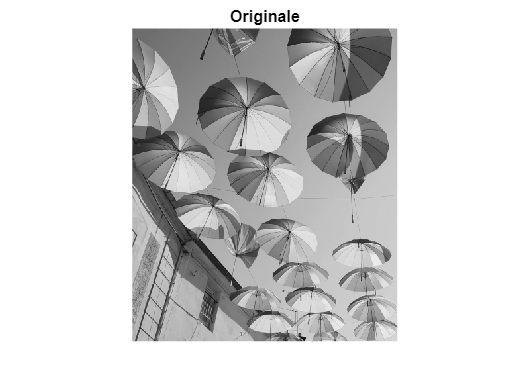

figure; image(uint8(y)); colormap(gray(256)); axis image; axis off; title('Originale') 

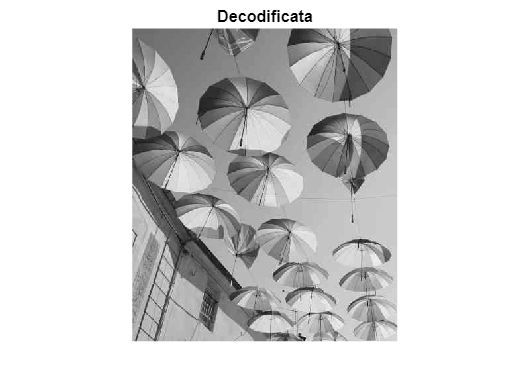

figure; image(reconstruct); colormap(gray(256)); axis image; axis off; title('Decodificata') 

Calcoliamo MSE e PSNR:

MSE = mean((y(:)-reconstruct(:)).^2) 

MSE =   22.342717161016949


PSNR = 10*log10(255*255/MSE)

PSNR =   34.639443730964352


Infine mostriamo l'errore di ricostruzione. Per valori del fattore di qualità alti, l'errore non ha una struttura riconoscibile. A qualità intermedia, si vede che l'errore è più grande vicino ai bordi degli oggetti (alte frequenze). A qualità bassa, si introduce anche l'effetto di "blocchettizzazione" ("discontinuità" tra i valori dei blocchi adiacenti). 

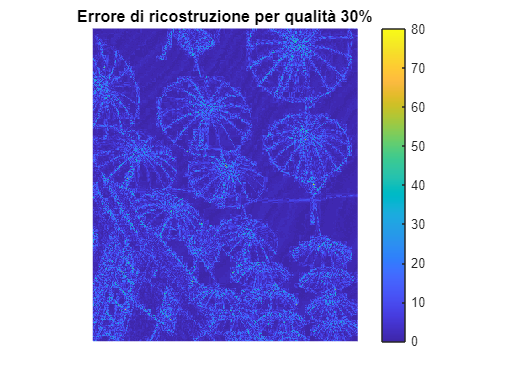

figure; imagesc(abs(double(y)-double(reconstruct))); colorbar; axis image; axis off; 
title(sprintf('Errore di ricostruzione per qualità %d%%',Q))

**Cambiate il fattore di qualità ed osservate i risultati. **